# PATCHED CONICS SOLUTION FOR INTERPLANETARY TRANSFERS.

*** Made by Sebastian Rodriguez Rosero, McGill Interstellar Flight Research group,***

Last updated on 12/22/2020

Info:

 Work in progress, algorithm expanded to all the planets in the solar  system. 

Earth to Mars transfers seem to work fine but other planets need validation. 

ALGORITHMS MAINLY FROM ORBITAL MECHANICS FOR ENGINEERING STUDENTS BY CURTIS.

%  Curtis, H. D. (2005). Chapter 3, 4, 5, 8. In Orbital mechanics for

% engineering students (pp. 107-398). Amsterdam: Butterworth-Heinemann.

 All CALCULATIONS HAVE BEEN DONE IN S.I UNITS. THESE ARE CONVERTED INTO THE MOST CONVENIENT UNIT ONCE THE RESULTS ARE DISPLAYED. 

**NOTE**: for simplicity, the sufix E refers to planet 1 and M to planet 2.

## loading up constants and unit conversion factors.

clear all; clc
[units,constant]=unitsandconstants();

## Initial Parameteres.

## choose the planets for the patched conics.

[planetdatadeparture,planetdataarrival,planet1,planet2]=chooseplanet();

                        INTERPLANETARY TRANSFER CALCULATOR 
Please choose from the following planets for the transfer: 
-Mercury 
-Venus 
-Earth 
-Mars 
-Jupiter 
-Saturn 
-Uranus 
-Neptune 
-Pluto

1) Departure planet: 


ans =     '
     1) Chosen planet: 101.000000
     1) Chosen planet: 97.000000
     1) Chosen planet: 114.000000
     1) Chosen planet: 116.000000
     1) Chosen planet: 104.000000'



2) Arrival planet: 


ans =     '
     2) Chosen planet: 109.000000
     2) Chosen planet: 97.000000
     2) Chosen planet: 114.000000
     2) Chosen planet: 115.000000'


%Input date of Departure
[date]=choosedates();


Would you like to put a specific time of launch/arrival?(y/n). (If not, default to 0 UTC)
DEPARTURE DATE: 
please input the calendar date
(1 <= month <= 12, 1 <= day <= 31, year = all digits!)
Chosen date: 9.000000/20.000000/2021.000000ARRIVAL DATE: 
please input the calendar date
(1 <= month <= 12, 1 <= day <= 31, year = all digits!)
Chosen date: 11.000000/4.000000/2021.000000

%Parking orbits around each of the planets, in meters. 
 [rorbitPlanet1, rorbitplanet2, AltitudePlanet1, AltitudePlanet2]=getDAOrbits( units,planetdatadeparture, planetdataarrival);

## Choose whether to perform a prograde or retrograde trajectory.

[chooseproretro]=chooseproretro();


Please choose either a prograde or retrograde trajectory. prograde="p" retrograde="r" 



clc
fprintf('                   INTERPLANETARY TRANSFER CALCULATOR \n')

                   INTERPLANETARY TRANSFER CALCULATOR 


fprintf('=========================================================================\n');

fprintf('                        '); 

fprintf(upper(planet1));

EARTH

fprintf(' TO ');

 TO 

fprintf(upper(planet2)); 

MARS

fprintf('\n')
fprintf('=========================================================================\n');

## Get State Vectors:

[R1,R2,vPlanet1,vPlanet2,TOF]=GetStateVectors(date, constant, units,planetdataarrival,planetdatadeparture);

------------------------------------------
 Departure date at : 2021 years, 9 months, 20 days, 0 hours(UT)

 Arrival date at Mars: 2021 years, 11 months, 4 days, 0 hours(UT)
------------------------------------------
------------------------------------------ 
 Orbital Parameters of departure planet orbit 
------------------------------------------
 Semimajor axis=1.000000 AU 
 Eccentricity= 0.016702 
 Inclination= 359.997218 deg 
 Right Ascension= 347.639690 deg 
 Longitude of Perihelion= 5902.581387 deg 
 Mean longitude= 358.808540 deg
 Angular Momentum= 4455105180453.973633 km^2/s 
 Argument of Perihelion= 115.379789 deg 
 Mean Anomaly= 255.789060 deg 
 Eccentric Anomaly= 254.865301 deg 
 True Anomaly= 253.943507 deg 

------------------------------------------
 Departure Planet State Vectors  
------------------------------------------
 R1=(150039213.155084 i, -7960418.278462 j, -1181.802325 k) km 
 r1= 150250237.087205 km

 V=(1.093503 i, 29.634922 j, -0.001417 k) km/s
 V(mag)= 29

## Solve Lambert's

 string =chooseproretro;
[v1,v2]=lambert(R1,R2,TOF,string,constant);

%Parameters of transfer orbit.
GetOrbitParaTransf(R1,v1, constant,units)

------------------------------------------
 
 Orbital Parameters of transfer orbit  
------------------------------------------

 Eccentricity= 2.278847 
 Inclination= 1.390489 deg 
 Right Ascension= 176.944420 deg 
 Argument of Periapsis= -70.989906 deg 
 Angular Momentum= 3153367792.681376 km^2/s 
 True Anomaly= 263.574848 deg 
------------------------------------------


## vector for V1, V2, V hyperbolic depart and arrival.

[v1mag,v2mag,vhyperDepartVECTOR, vhyperArrivalVECTOR, vhyperDepart, vhyperArrival]=getHyperVel(v1,v2,vPlanet1, vPlanet2);

## delta Vs.

[DeltaVplanet1, DeltaVplanet2, vpMh]=GetDVcircular(vhyperDepart, vhyperArrival, planetdatadeparture, planetdataarrival);

## Eccetricity of the hyperbola

 [e, eM]=getEccentricityHyper(planetdatadeparture,planetdataarrival, vhyperDepart, vhyperArrival);

## Display results of patched conics

fprintf('\n-------------------------------------------------\n')


-------------------------------------------------


fprintf( 'LAUNCH AND ARRIVAL CONDITIONS')

LAUNCH AND ARRIVAL CONDITIONS

fprintf('\n-------------------------------------------------\n')


-------------------------------------------------


fprintf(' Altitude of initial orbit at periapsis= %.1f\tkm \n Altitude of final orbit at periapsis= %.1f\tkm \n TOF= %.1f\tDays \n', AltitudePlanet1, AltitudePlanet2, TOF/units.day);   

 Altitude of initial orbit at periapsis= 100.0	km 
 Altitude of final orbit at periapsis= 200.0	km 
 TOF= 45.0	Days 


fprintf('\n-------------------------------------------------\n')


-------------------------------------------------


fprintf( ' RESULTS ');

 RESULTS 

fprintf('\n-------------------------------------------------\n')


-------------------------------------------------


fprintf(' V1= %f\tkm/s \n V2= %f\tkm/s \n Hyperbolic excess leaving planet 1 = %f\tkm/s \n Hyperbolic excess arriving to planet 2 = %f\tkm/s \n Delta V at starting orbit in planet 1= %f\tkm/s \n Delta V for circular final orbit around planet 2= %f\tkm/s \n Eccentricity of hyperbola leaving planet 1= %.4f \n Eccentricity of the hyperbola arriving to planet 2= %.4f \n', v1mag/units.KM, v2mag/units.KM ,vhyperDepart/units.KM, vhyperArrival/units.KM, DeltaVplanet1/units.KM, -DeltaVplanet2/units.KM, e, eM);

 V1= 95.883059	km/s 
 V2= 92.373133	km/s 
 Hyperbolic excess leaving planet 1 = 93.484111	km/s 
 Hyperbolic excess arriving to planet 2 = 93.701272	km/s 
 Delta V at starting orbit in planet 1= 86.244808	km/s 
 Delta V for circular final orbit around planet 2= 90.284512	km/s 
 Eccentricity of hyperbola leaving planet 1= 140.8371 
 Eccentricity of the hyperbola arriving to planet 2= 697.1889 






%

#### TRAJECTORY GRAPHING

*SECTION AHEAD CURRENTLY UNDER RENOVATIONS*

 
%Works for some planets. 
while(1)  
   fprintf('would you like to plot this trajectory (y = yes, n = no)\n');
   slct2 = input('? ', 's');
   if (slct2 == 'y' || slct2 == 'n')
      break;
   end 
   fprintf(' \n Oops! \nInvalid input, try again :) \n');
   
end

would you like to plot this trajectory (y = yes, n = no)


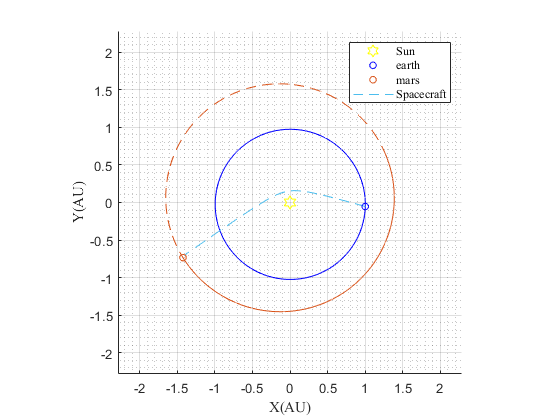


if slct2 == 'y' 
 GetTransferplot(R1, vPlanet1, R2, vPlanet2,v1,constant,units,planet1,planet2,planetdataarrival, planetdatadeparture);
end